# Oscillator

## Transient

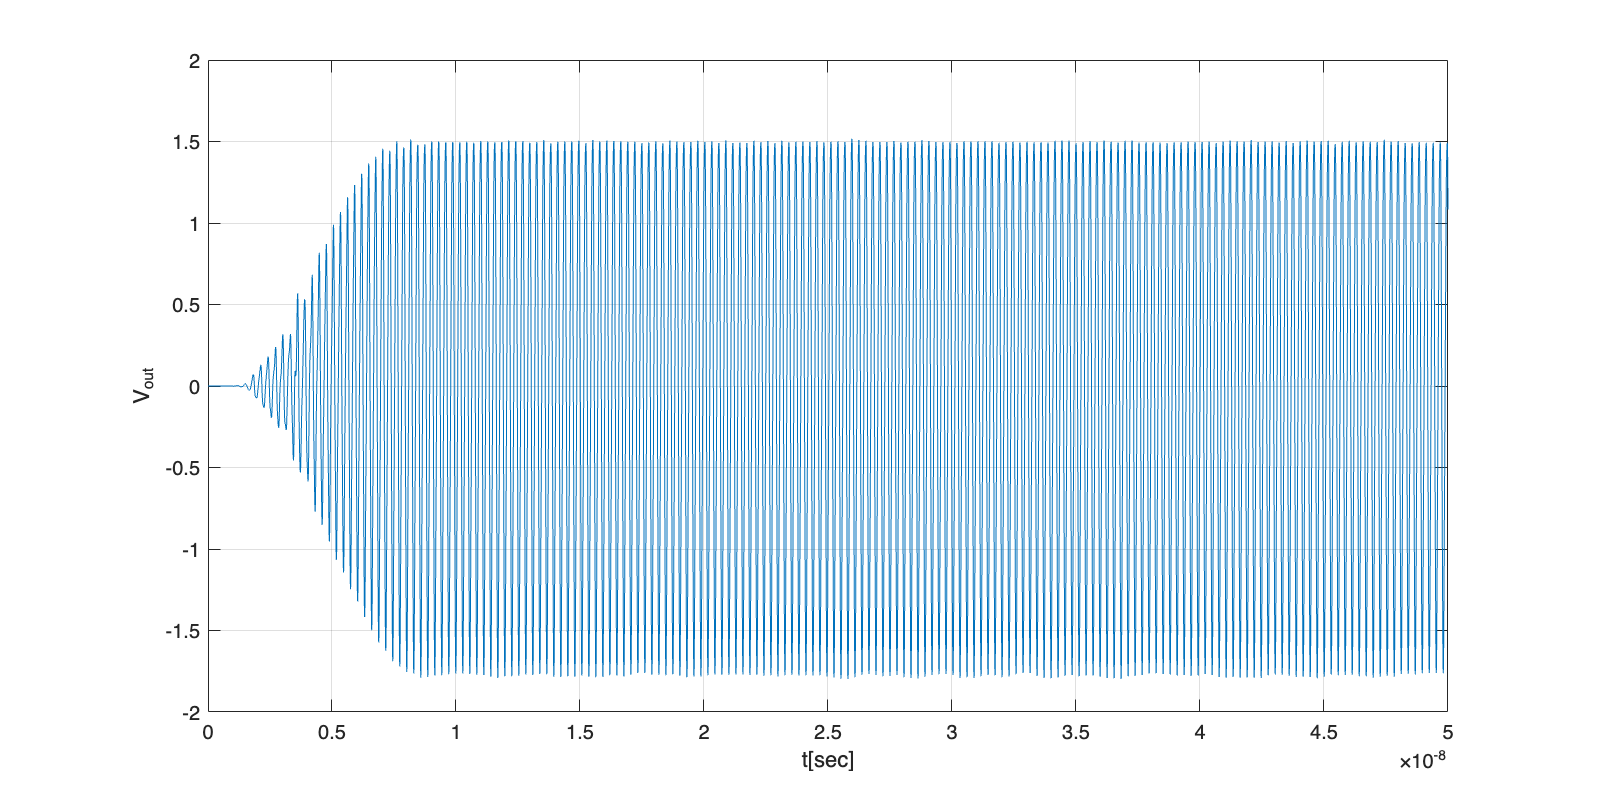

% Load the data from VCO_trans.matlab
VCO_trans = readmatrix('Osc/VCO_trans.matlab', 'FileType', 'text');

% Extract x and y values
x = VCO_trans(:, 1); % First column
y = VCO_trans(:, 2); % Second column

figure; set(gcf, 'Position', [100, 100, 800, 400]); % Adjust figure size as needed
% Plot the data
plot(x, y); % '-o' connects points with lines and marks data points with circles

% Add labels and title
xlabel('t[sec]');
ylabel('V_{out}');

% Add grid
grid on;

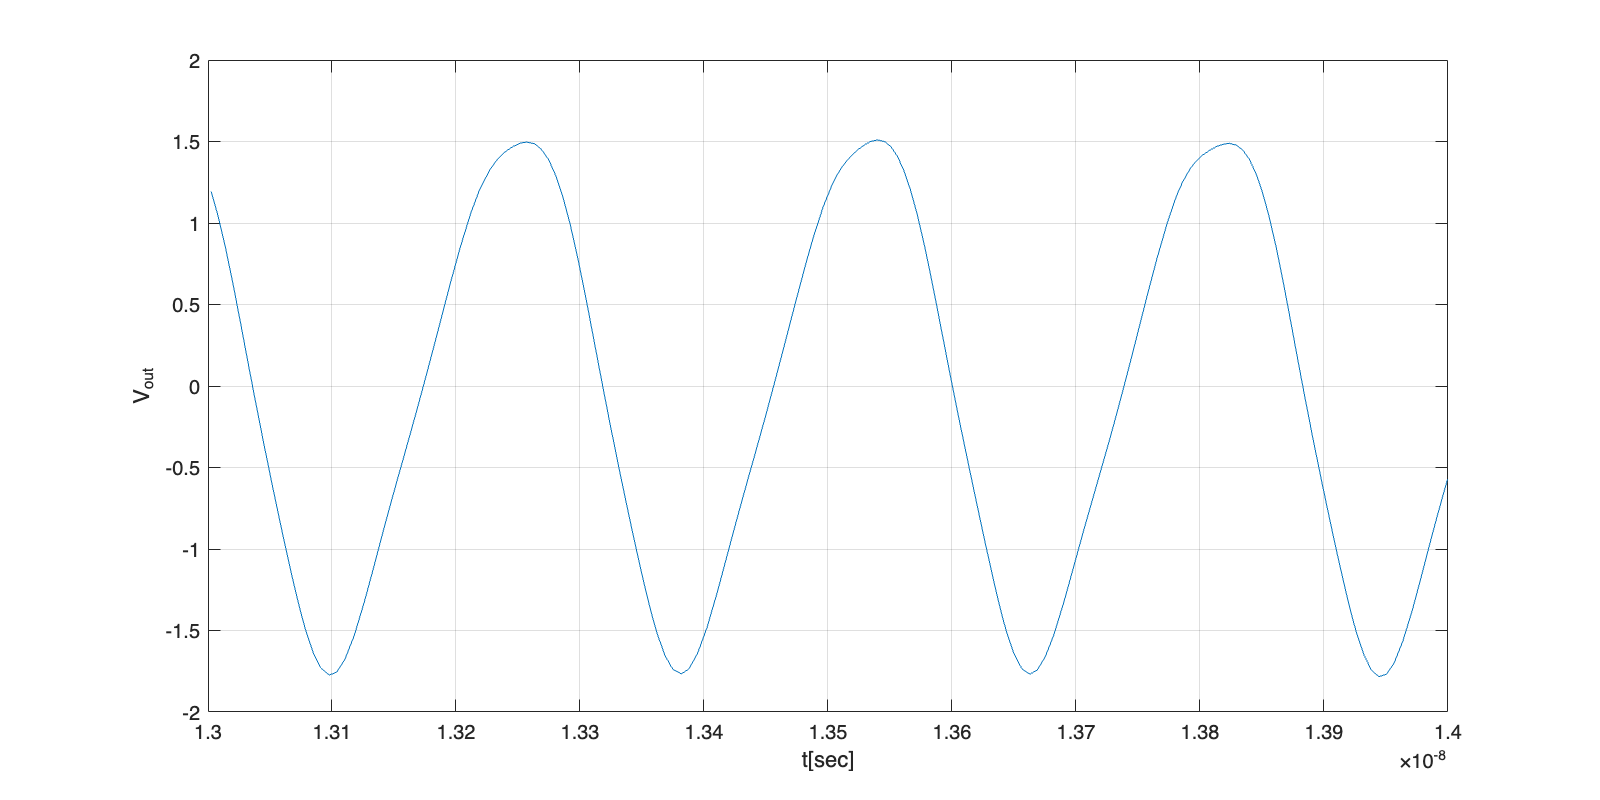

% Save the figure as an EPS file
%saveas(gcf, 'VCO_trans.svg', 'svg');
% Filter data 
indices = (x >= 13e-9) & (x <= 14e-9);
x = x(indices);
y = y(indices);

figure; set(gcf, 'Position', [100, 100, 800, 400]); % Adjust the numbers as needed
% Plot the data
plot(x, y); % '-o' connects points with lines and marks data points with circles

% Add labels and title
xlabel('t[sec]');
ylabel('V_{out}');

% Add grid
grid on;
saveas(gcf, 'VCO_trans_zoom.svg', 'svg');

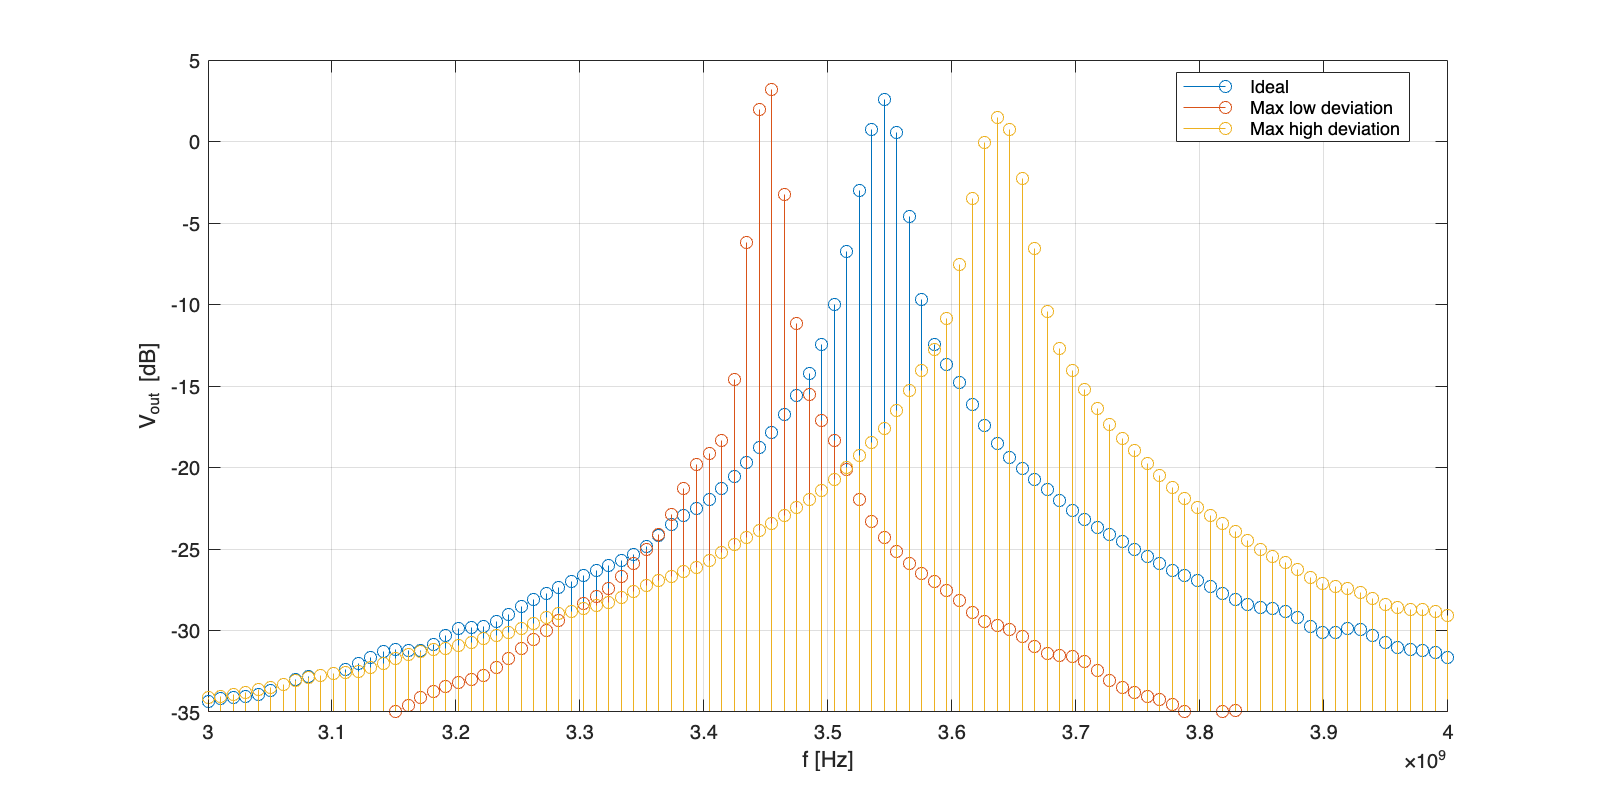

% Load the data from VCO_trans.matlab
VCO_spec = readmatrix('Osc/VCO_spec.matlab', 'FileType', 'text');
VCO_spec_low = readmatrix('Osc/VCO_spec_low.matlab', 'FileType', 'text');
VCO_spec_high = readmatrix('Osc/VCO_spec_high.matlab', 'FileType', 'text');

% Extract x and y values
x = VCO_spec(:, 1); % First column
y = VCO_spec(:, 2); % Second column
x_low = VCO_spec_low(:, 1); % First column
y_low = VCO_spec_low(:, 2); % Second column
x_high = VCO_spec_high(:, 1); % First column
y_high = VCO_spec_high(:, 2); % Second column

% Filter data where spectrum__net0_X is between [3.3e9, 3.7e9]
indices = (x >= 3e9) & (x <= 4e9);

x = x(indices);
y = y(indices);
x_low = x_low(indices);
y_low = y_low(indices);
x_high = x_high(indices);
y_high = y_high(indices);

% Smooth the data using interpolation
x_interp = linspace(min(x), max(x), 100); % Interpolation points

y_smooth = interp1(x, y, x_interp, 'spline');
y_low_smooth = interp1(x_low, y_low, x_interp, 'spline');
y_high_smooth = interp1(x_high, y_high, x_interp, 'spline');

figure; set(gcf, 'Position', [100, 100, 800, 400]); % Adjust figure size as needed

% Plot the data with smoothed curves
% Define x_interp and y_smooth, y_low_smooth, y_high_smooth as your data

y_lim = -35;

% Plot the Ideal stems starting from -100
h1 = stem(x_interp, y_smooth, 'DisplayName', 'Ideal'); % Ideal plot with circles marking data points
set(h1, 'BaseValue', y_lim); % Set the base value to -100
hold on;

% Plot the Max low deviation stems starting from -100
h2 = stem(x_interp, y_low_smooth, 'DisplayName', 'Max low deviation'); % Smoothed low deviation plot
set(h2, 'BaseValue', y_lim); % Set the base value to -100

% Plot the Max high deviation stems starting from -100
h3 = stem(x_interp, y_high_smooth, 'DisplayName', 'Max high deviation'); % Smoothed high deviation plot
set(h3, 'BaseValue', y_lim); % Set the base value to -100

%hold off;
%legend;
% Find peaks for each curve
[~, locs_y] = findpeaks(y_smooth);
[~, locs_y_low] = findpeaks(y_low_smooth);
[~, locs_y_high] = findpeaks(y_high_smooth);

% Mark peaks on the plot with data tips
hold on;
dcm_obj = datacursormode(gcf);
set(dcm_obj, 'UpdateFcn', @dataTipCallback);

% Add labels and title
xlabel('f [Hz]');
ylabel('V_{out} [dB]'); ylim([y_lim, 5]);

legend('show', 'Location', 'best', 'Interpreter', 'none');

% Add grid
grid on;

% Save the plot as a .png file
saveas(gcf, 'VCO_spec.svg', 'svg');


function txt = dataTipCallback(~, event)
    pos = get(event, 'Position');
    txt = {sprintf('x: %.2e Hz', pos(1)), ...
           sprintf('y: %.2f dB', pos(2))};
end

## Matching

%{
% Load S-parameter data from the file
filename = 'matching/matching_network.txt';
data = readtable(filename, 'FileType', 'text', 'Delimiter', '\t', 'HeaderLines', 1);

% Extract frequency and S-parameters with magnitude only
frequency = data{:, 1};  % Assuming frequency is the first column

% Initialize S-parameters arrays
S11_dB = zeros(height(data), 1);
S21_dB = zeros(height(data), 1);
S12_dB = zeros(height(data), 1);
S22_dB = zeros(height(data), 1);

% Extract and convert S-parameters to dB, ignoring phase
for i = 1:height(data)
    S11_str = split(data{i, 2}, ',');
    S21_str = split(data{i, 3}, ',');
    S12_str = split(data{i, 4}, ',');
    S22_str = split(data{i, 5}, ',');
    
    S11_dB(i) = str2double(erase(S11_str{1}, 'dB'));
    S21_dB(i) = str2double(erase(S21_str{1}, 'dB'));
    S12_dB(i) = str2double(erase(S12_str{1}, 'dB'));
    S22_dB(i) = str2double(erase(S22_str{1}, 'dB'));
end

% Create subplots
figure; set(gcf, 'Position', [100, 100, 1200, 800]); % Adjust the numbers as needed

subplot(2, 2, 1);
plot(frequency, S11_dB);
title('S11 (dB)');
xlabel('Frequency (Hz)');
ylabel('S11 (dB)');
grid on;

subplot(2, 2, 2);
plot(frequency, S21_dB);
title('S21 (dB)');
xlabel('Frequency (Hz)');
ylabel('S21 (dB)');
grid on;

subplot(2, 2, 3);
plot(frequency, S12_dB);
title('S12 (dB)');
xlabel('Frequency (Hz)');
ylabel('S12 (dB)');
grid on;

subplot(2, 2, 4);
plot(frequency, S22_dB);
title('S22 (dB)');
xlabel('Frequency (Hz)');
ylabel('S22 (dB)');
grid on;

% Adjust layout for better visualization
saveas(gcf, 'matching_S_params.svg', 'svg');

%}
% Load the data
data = readmatrix('matching/matching_network.txt');

% Extract frequency and complex values
freq = data(:, 1);
complex_values = data(:, 2) + 1i * data(:, 3);

Index in position 2 exceeds array bounds. Index must not exceed 2.


% Compute the absolute value of the complex values
abs_values = abs(complex_values);

% Plot the data
figure;
plot(freq, abs_values);
xlabel('Frequency (Hz)');
ylabel('Impedance Transformation');
grid on;

## Antenna

% Assuming data is saved in S11.txt with columns: Frequency (GHz), S11 Magnitude
data = readtable('antenna/S11.txt');
frequency = table2array(data(:, 1));  % Frequency values in GHz
S11_mag = table2array(data(:, 2));    % S11 magnitude values

% Find indices where S11 magnitude crosses -10
crossingIndices = find(abs(S11_mag + 10) < 0.1); % Adjust the tolerance if needed

% Plot S11
figure; set(gcf, 'Position', [100, 100, 1200, 400]); % Adjust the figure size as needed
plot(frequency, S11_mag);
hold on;
plot(frequency, -10*ones(length(frequency)), 'r');

xlabel('Frequency (GHz)');
ylabel('S11 Magnistude');
grid on;

% Save plot as PNG
saveas(gcf, 'S11.eps', 'epsc');

ax2 = gca;
chart = ax2.Children(1);
datatip(chart,3.441,-10);
chart = ax2.Children(2);
datatip(chart,3.642,-10);
% Read data from file
data = readtable('antenna/FF.txt', 'Delimiter', ' ', 'MultipleDelimsAsOne', true);

% Extract columns
Theta_deg = table2array(data(:, 2));  % Assuming the exact column name in your data
Realized_gain_dBi = table2array(data(:, 4));  % Assuming the exact column name in your data
phi = table2array(data(:, 3));  % Assuming the exact column name in your data

%indices1 = (phi >= 0) & (phi <= 90);
%indices2 = (phi > 90) & (phi <= 270);

%Theta_deg = [Theta_deg(indices1), 360-Theta_deg(indices2)];
%Realized_gain_dBi = [Realized_gain_dBi(indices1) Realized_gain_dBi(indices2)];

% Identify the index where Theta_degree is 180
index_180 = find(Theta_deg == 180, 1); % Find the first occurrence of 180

% Check if the index is found
if isempty(index_180)
    error('Theta_degree does not contain the value 180.');
else
    % Perform 360 - value for all indices after the identified index
    Theta_deg((index_180 + 1):end) = 360 - Theta_deg((index_180 + 1):end);
end

theta = table2array(data(:, 2));  % Assuming the exact column name in your data
phi = table2array(data(:, 3));  % Assuming the exact column name in your data
abs_grlz = table2array(data(:, 4));  % Assuming the exact column name in your data


% Convert theta to radians for polar plot
theta_rad = deg2rad(Theta_deg);

% Create polar plot
figure; set(gcf, 'Position', [100, 100, 500, 500]); % Adjust the numbers as needed
polarplot(theta_rad, abs_grlz, 'LineWidth', 1);
ax = gca;  % Get current axes handle
ax.Box = 'on';  % Display the axes box
hold on;

% Add additional elements (e.g., markers or additional plots)
% polarplot(theta_rad, abs_theta, 'b--', 'LineWidth', 2);
% polarplot(theta_rad, abs_phi, 'g:', 'LineWidth', 2);

% Add legend
%legend('farfield (f=3.5)');

% Add title and labels
ax = gca;
ax.ThetaTickLabel = {'0', '30', '60', '90', '120', '150', '180', '210', '240', '270', '300', '330'};
ax.RLim = [-30 10];  % Adjust radial limits as needed

% Display text annotations
dim = [0.05, 0.05, 0.3, 0.3];  % Adjust the left position to move the box to the left
%str = {'Frequency = 3.5 GHz', 'Main lobe magnitude = 6.22 dBi', 'Main lobe direction = 0.0 deg.', 'Angular width (3 dB) = 79.9 deg.', 'Side lobe level = -15.6 dBi'};
%annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on');

% Adjust the plot for better visualization
set(gca, 'ThetaDir', 'clockwise');
set(gca, 'ThetaZeroLocation', 'top');

saveas(gcf, 'FF_p.svg', 'svg');

## 3D Plot

% Read data from file
data3d = readtable('antenna/FF3d.txt', 'Delimiter', ' ', 'MultipleDelimsAsOne', true);

% Assuming data3d is your input table
theta = table2array(data3d(:, 2));  % Assuming the exact column name in your data
phi = table2array(data3d(:, 3));    % Assuming the exact column name in your data
abs_grlz = table2array(data3d(:, 4));  % Assuming the exact column name in your data

% Convert degrees to radians
theta = deg2rad(theta);
phi = deg2rad(phi);

% Create a finer grid for phi (e.g., every 1 degree)
phi_fine = deg2rad(0:1:359);

% Create a unique list of theta values
theta_unique = unique(theta);

% Initialize the grid for interpolated abs_grlz values
abs_grlz_grid = zeros(length(theta_unique), length(phi_fine));

% Interpolate abs_grlz values for each unique theta value
for i = 1:length(theta_unique)
    % Find the indices of the current theta value
    idx = find(theta == theta_unique(i));
    
    % Interpolate abs_grlz values for the current theta value
    abs_grlz_grid(i, :) = interp1(phi(idx), abs_grlz(idx), phi_fine, 'linear', 'extrap');
end

% Convert to Cartesian coordinates for plotting
X = abs_grlz_grid .* sin(Theta) .* cos(Phi);
Y = abs_grlz_grid .* sin(Theta) .* sin(Phi);
Z = abs_grlz_grid .* cos(Theta);

% Plot the surface
figure;
surf(X, Y, Z, 'EdgeColor', 'none');
colorbar;  % Add a color bar to visualize the values
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Interpolated Surface Plot');
axis equal;  % Equal scaling for all axes